**Open the “with attention” and “without attention” EEG files in MATLAB.**

**-**Trims the first 30 seconds to remove the very pronounced amplifier drift and settling artifacts

-Removes noisy channels (FC5 and Pz) that weren't working during the experiment and subtracts DC offsets from each channel

-Merges the two counting runs into a single continuous dataset with no gap

-Summary stats

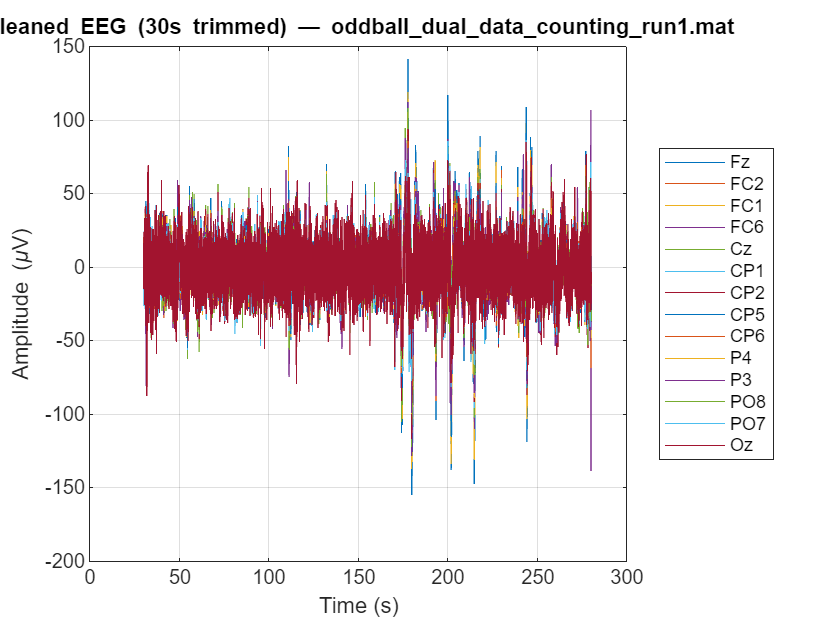

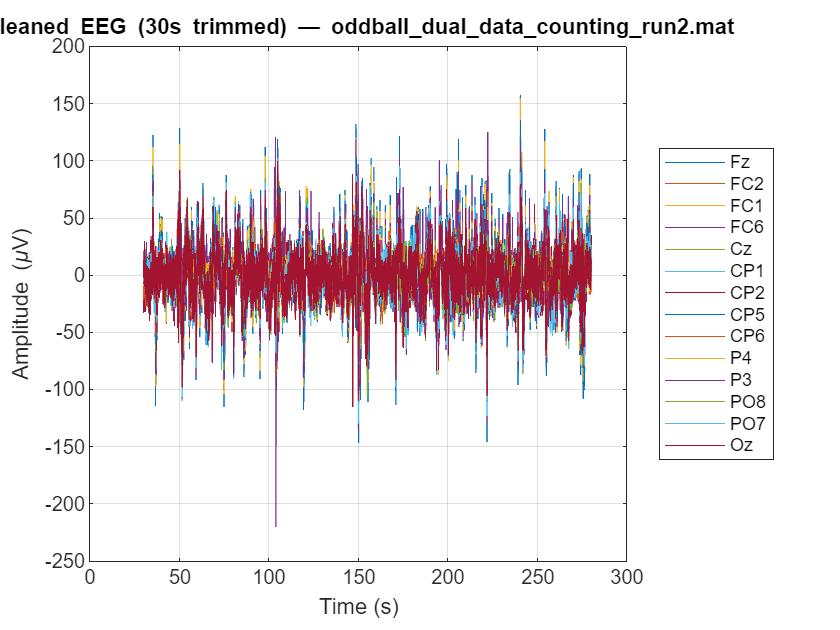

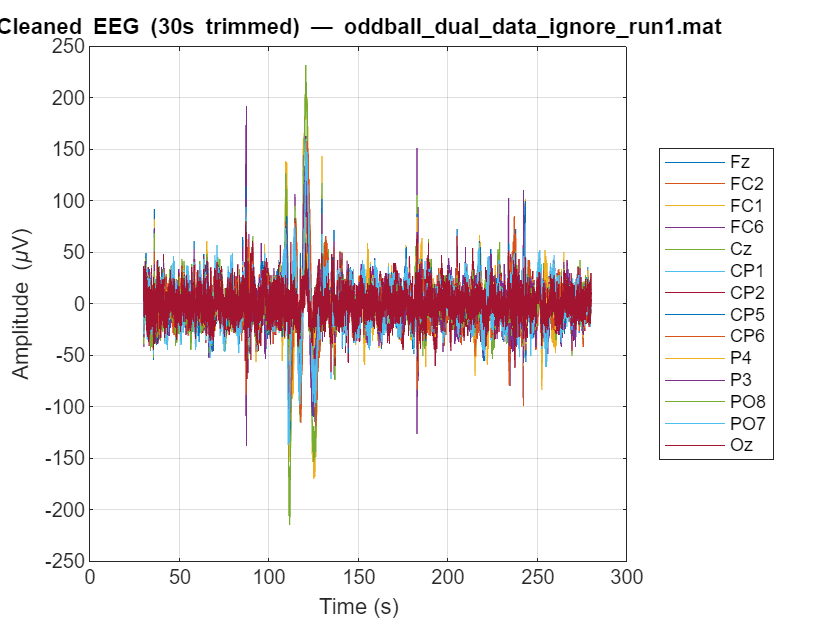

clear; clc; close all;

fs = 256;                       % Hz
trimDuration = 30;              %seconds
badCh = [5, 11];                % we need to get rid of FC5, Pz (within just the 16 EEG chans)s
allChannels = {'Fz','FC2','FC1','FC6','FC5','Cz','CP1','CP2', ...
               'CP5','CP6','Pz','P4','P3','PO8','PO7','Oz'};
goodChannels = allChannels; goodChannels(badCh) = [];

files = { ...
  'oddball_dual_data_counting_run1.mat', ...
  'oddball_dual_data_counting_run2.mat', ...
  'oddball_dual_data_ignore_run1.mat'};

%here is the container that we made for our good runs 
clean = struct();

for i = 1:numel(files)
    fname = files{i};
    S  = load(fname);
    ts = S.trigger;

    % Extract
    t   = ts.Time;         % Nx1
    X   = ts.Data;         % Nx17
    EEG = X(:,1:16);       % 16 EEG channels <-- just the 16
    trig= X(:,17);         %0 for nothing, 1 for 500Hz, 2 for 900Hz

    %trim the first 30seconds
    idx = t > trimDuration;
    t   = t(idx);  EEG = EEG(idx,:);  trig = trig(idx);

    %remove those bad 2 channels 
    EEG(:,badCh) = [];

    %drift
    EEG = EEG - mean(EEG,1);

    %for concatenation
    if contains(fname,'counting_run1')
        tag = 'counting_run1';
    elseif contains(fname,'counting_run2')
        tag = 'counting_run2';
    else
        tag = 'ignore_run1';
    end

    % store the outputs for later
    clean.(tag).t    = t;
    clean.(tag).EEG  = EEG;
    clean.(tag).trig = trig;

    %quick summary starts + little helpful plot


    figure('Name',[fname ' (cleaned)'],'NumberTitle','off');
    plot(t, EEG); grid on
    xlabel('Time (s)'); ylabel('Amplitude (\muV)');
    title(sprintf('Cleaned EEG (30s trimmed) — %s', strrep(fname,'_','\_')));
    legend(goodChannels, 'Location','eastoutside');
end

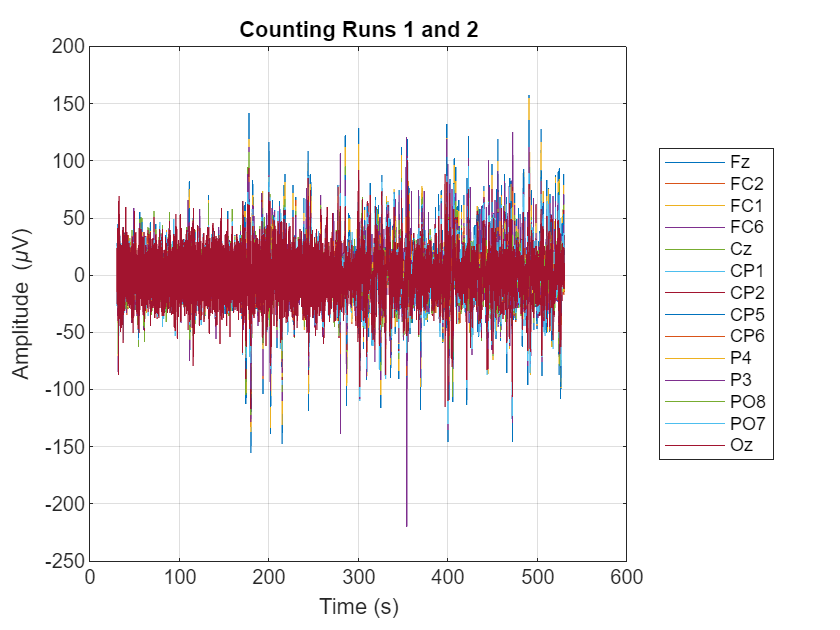


%start of the building process for the combined counting recording (omit
%30s and then join wihtout the gap)
t1   = clean.counting_run1.t;
EEG1 = clean.counting_run1.EEG;
tr1  = clean.counting_run1.trig;

t2   = clean.counting_run2.t;
EEG2 = clean.counting_run2.EEG;
tr2  = clean.counting_run2.trig;

%re-zero t2, then we shift to follow immediately after t1
t2_shift = (t2 - t2(1)) + t1(end) + 1/fs;

%actually concatinating
t_counting    = [t1; t2_shift];
EEG_counting  = [EEG1; EEG2];
trig_counting = [tr1; tr2];

figure('Name','Combined Counting','NumberTitle','off');
plot(t_counting, EEG_counting); grid on
xlabel('Time (s)'); ylabel('Amplitude (\muV)');
title('Counting Runs 1 and 2');
legend(goodChannels, 'Location','eastoutside');


% future vars
%clean ignore 
t_ignore_clean   = clean.ignore_run1.t;
EEG_ignore_clean = clean.ignore_run1.EEG;
trig_ignore_clean= clean.ignore_run1.trig;

%cleaned concat counting ds
t_counting_clean    = t_counting;
EEG_counting_clean  = EEG_counting;
trig_counting_clean = trig_counting;

%just incase
t_run1_clean   = t1;   EEG_run1_clean = EEG1;   trig_run1_clean = tr1;
t_run2_clean   = t2;   EEG_run2_clean = EEG2;   trig_run2_clean = tr2;

disp('Saved variables: t_ignore_clean, EEG_ignore_clean, trig_ignore_clean, t_counting_clean, EEG_counting_clean, trig_counting_clean, plus per-run *_clean.');

Saved variables: t_ignore_clean, EEG_ignore_clean, trig_ignore_clean, t_counting_clean, EEG_counting_clean, trig_counting_clean, plus per-run *_clean.


**Plot the average ERP responses to the frequent and infrequent tones for the “with attention” and “without**

**attention” conditions for all electrodes and determine the electrodes with the strongest response (5 pts)**

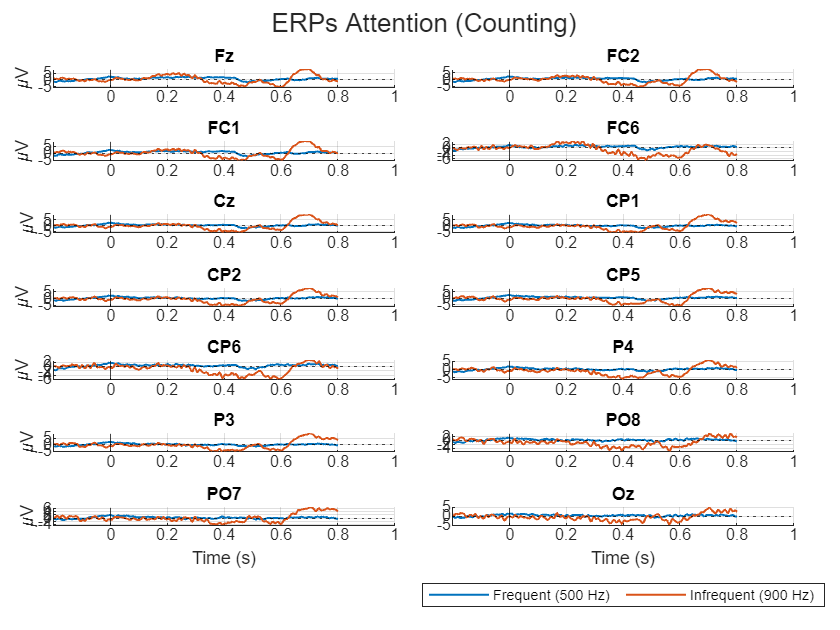

% use prev vars from prev cell
%random assumptions from literature
fs = 256;
win_pre  = 0.2;          % in ms, 200 ms before tone
win_post = 0.8;          % 800ms seconds after tone
nPre  = round(win_pre*fs);
nPost = round(win_post*fs);
tERP  = (-nPre:nPost)/fs;

%order
chanNames = {'Fz','FC2','FC1','FC6','Cz','CP1','CP2','CP5','CP6','P4','P3','PO8','PO7','Oz'};

%build the tone onset indices, rises from 500 to 900 or vis versa
EEG = EEG_counting_clean; trig = trig_counting_clean;
%onsets for 500 Hz (1) and 900 Hz (2)
on_500 = find(trig==1 & [0; trig(1:end-1)]==0);
on_900 = find(trig==2 & [0; trig(1:end-1)]==0);
%only keep what fits in recording bounds 
on_500 = on_500(on_500-nPre>=1 & on_500+nPost<=size(EEG,1));
on_900 = on_900(on_900-nPre>=1 & on_900+nPost<=size(EEG,1));

% init erp Matrix, to hold later data
erp_count_freq = nan(nPre+nPost+1, size(EEG,2)); % build basebline correct epochs
erp_count_dev  = nan(nPre+nPost+1, size(EEG,2)); %extracts the window from 200 to 800ms
if ~isempty(on_500) %then subtracks the pre stimulus mean 
    epochs = zeros(nPre+nPost+1, size(EEG,2), numel(on_500), 'like', EEG);
    for k = 1:numel(on_500)
        seg = EEG(on_500(k)-nPre:on_500(k)+nPost, :);
        seg = seg - mean(seg(1:nPre,:),1);  % our baseline
        epochs(:,:,k) = seg;
    end
    erp_count_freq = mean(epochs,3,'omitnan');
end
if ~isempty(on_900)
    epochs = zeros(nPre+nPost+1, size(EEG,2), numel(on_900), 'like', EEG);
    for k = 1:numel(on_900)
        seg = EEG(on_900(k)-nPre:on_900(k)+nPost, :);
        seg = seg - mean(seg(1:nPre,:),1);
        epochs(:,:,k) = seg;
    end
    erp_count_dev = mean(epochs,3,'omitnan');
end

% repeat the entire process but without attention this time. 
EEG = EEG_ignore_clean; trig = trig_ignore_clean;
on_500 = find(trig==1 & [0; trig(1:end-1)]==0);
on_900 = find(trig==2 & [0; trig(1:end-1)]==0);
on_500 = on_500(on_500-nPre>=1 & on_500+nPost<=size(EEG,1));
on_900 = on_900(on_900-nPre>=1 & on_900+nPost<=size(EEG,1));

erp_ign_freq = nan(nPre+nPost+1, size(EEG,2));
erp_ign_dev  = nan(nPre+nPost+1, size(EEG,2));
if ~isempty(on_500)
    epochs = zeros(nPre+nPost+1, size(EEG,2), numel(on_500), 'like', EEG);
    for k = 1:numel(on_500)
        seg = EEG(on_500(k)-nPre:on_500(k)+nPost, :);
        seg = seg - mean(seg(1:nPre,:),1);
        epochs(:,:,k) = seg;
    end
    erp_ign_freq = mean(epochs,3,'omitnan');
end
if ~isempty(on_900)
    epochs = zeros(nPre+nPost+1, size(EEG,2), numel(on_900), 'like', EEG);
    for k = 1:numel(on_900)
        seg = EEG(on_900(k)-nPre:on_900(k)+nPost, :);
        seg = seg - mean(seg(1:nPre,:),1);
        epochs(:,:,k) = seg;
    end
    erp_ign_dev = mean(epochs,3,'omitnan');
end

%really cool plots for all of the electrodes (can see individual p300s)
figure('Name','ERPs w/ attention (Counting)','NumberTitle','off');
tiledlayout(7,2,'TileSpacing','compact','Padding','compact');
for ch = 1:numel(chanNames)
    nexttile; hold on; grid on
    plot(tERP, erp_count_freq(:,ch), 'LineWidth',1);
    plot(tERP, erp_count_dev(:,ch),  'LineWidth',1);
    xline(0,'k-'); yline(0,'k:');
    title(chanNames{ch});
    if ch>12, xlabel('Time (s)'); end
    if any(ch==[1,3,5,7,9,11,13]), ylabel('\muV'); end
end
legend({'Frequent (500 Hz)','Infrequent (900 Hz)'},'Location','southoutside','Orientation','horizontal');
sgtitle('ERPs Attention (Counting)');

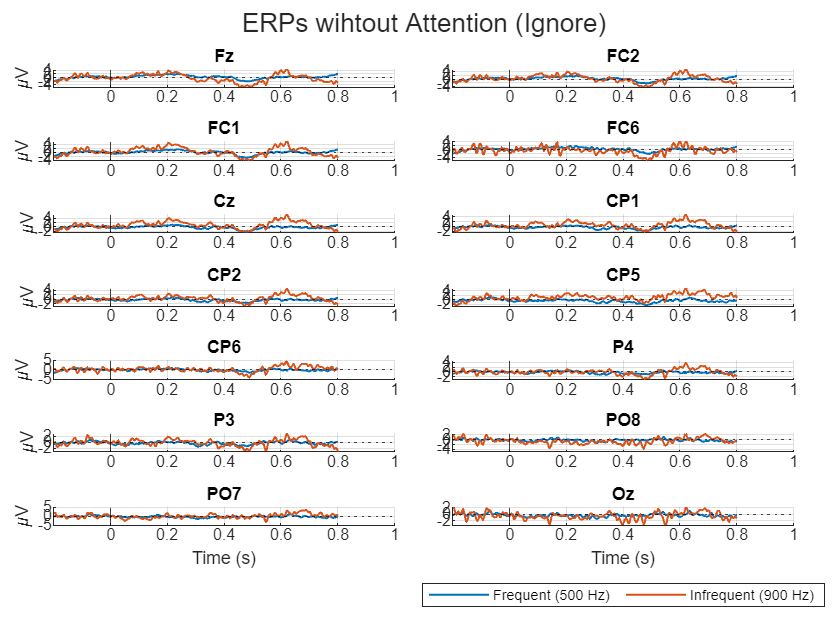


% electrode plots for without attention
figure('Name','ERPs w/o attention (Ignore)','NumberTitle','off');
tiledlayout(7,2,'TileSpacing','compact','Padding','compact');
for ch = 1:numel(chanNames)
    nexttile; hold on; grid on
    plot(tERP, erp_ign_freq(:,ch), 'LineWidth',1);
    plot(tERP, erp_ign_dev(:,ch),  'LineWidth',1);
    xline(0,'k-'); yline(0,'k:');
    title(chanNames{ch});
    if ch>12, xlabel('Time (s)'); end
    if any(ch==[1,3,5,7,9,11,13]), ylabel('\muV'); end
end
legend({'Frequent (500 Hz)','Infrequent (900 Hz)'},'Location','southoutside','Orientation','horizontal');
sgtitle('ERPs wihtout Attention (Ignore)');


% now to quantify which have the strongest ERP responses, P300 window. 
winMask = tERP>=0.25 & tERP<=0.60;                 % 250–600 ms, expand to 600 since most electrode plots are extending
diff_count = erp_count_dev - erp_count_freq;       % deviant - then frequent
diff_ign   = erp_ign_dev   - erp_ign_freq;

% measuring the peak abs amplitude, per channel in the window we made. 
pkCount = max(abs(diff_count(winMask,:)),[],1,'omitnan');
pkIgn   = max(abs(diff_ign(winMask,:)),[],1,'omitnan');

[~, ordCount] = sort(pkCount,'descend'); % ranking the electrodes by their p300 strength 
[~, ordIgn]   = sort(pkIgn,'descend');

%print out the top electrods and their values, will revisit this more later. 
fprintf('\nTop electrodes (WITH attention) by |deviant - frequent| in 0.25-0.60 s:\n');


Top electrodes (WITH attention) by |deviant - frequent| in 0.25-0.60 s:


for k = 1:min(5, numel(chanNames))
    fprintf('  %s: %.2f µV\n', chanNames{ordCount(k)}, pkCount(ordCount(k)));
end

  CP6: 6.80 µV
  PO8: 6.54 µV
  P4: 6.46 µV
  FC6: 6.27 µV
  CP5: 6.13 µV



fprintf('\nTop electrodes (WITHOUT attention) by |deviant - frequent| in 0.25-0.60 s:\n');


Top electrodes (WITHOUT attention) by |deviant - frequent| in 0.25-0.60 s:


for k = 1:min(5, numel(chanNames))
    fprintf('  %s: %.2f µV\n', chanNames{ordIgn(k)}, pkIgn(ordIgn(k)));
end

  FC1: 4.30 µV
  Cz: 4.26 µV
  CP5: 4.24 µV
  FC2: 3.94 µV
  Fz: 3.77 µV


**Plot the average ERP responses to the frequent and infrequent tones for the “with attention” and “without**

**attention” cases, averaged over the strongest electrodes (2 pts).**

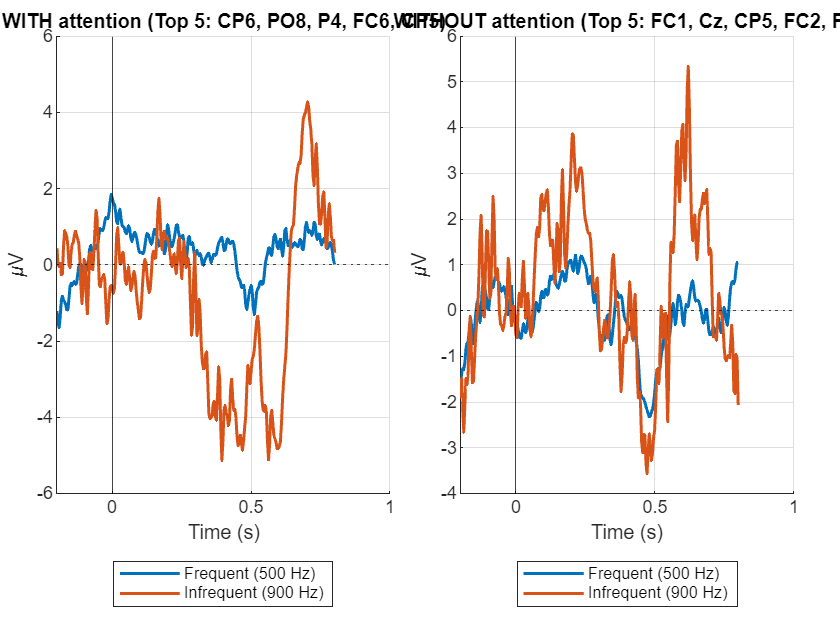

% pick a window from which to score strenth 
winMask = tERP >= 0.25 & tERP <= 0.60;   % 250–600 ms again a little wider, larger effectiveness. 
topK = 5;                                 % lets just do 5, not specified
% find strongest channels, computes difference wave
% finds abs peak amplitude per channel
%sorts channels by their peaks to find largest p300 effect 
diff_count = erp_count_dev - erp_count_freq;
pkCount = max(abs(diff_count(winMask,:)), [], 1, 'omitnan');
[~, ordCount] = sort(pkCount, 'descend');
idxTopCount = ordCount(1:min(topK, numel(ordCount)));
namesTopCount = chanNames(idxTopCount);

% av ERPs over the strongest electrodes w attention. collapses multi
% channel --> one average waveform per tone type 
avg_count_freq = mean(erp_count_freq(:, idxTopCount), 2, 'omitnan');
avg_count_dev  = mean(erp_count_dev(:,  idxTopCount), 2, 'omitnan');

% w/o attention same thing
diff_ign = erp_ign_dev - erp_ign_freq;
pkIgn = max(abs(diff_ign(winMask,:)), [], 1, 'omitnan');
[~, ordIgn] = sort(pkIgn, 'descend');
idxTopIgn = ordIgn(1:min(topK, numel(ordIgn)));
namesTopIgn = chanNames(idxTopIgn);
avg_ign_freq = mean(erp_ign_freq(:, idxTopIgn), 2, 'omitnan');
avg_ign_dev  = mean(erp_ign_dev(:,  idxTopIgn), 2, 'omitnan');

%% plotting
% creates figure with 2 side by side panels, each pannel plots the av
% frequent v infrequent ERPS 
figure('Name','ERPs averaged over strongest electrodes','NumberTitle','off');
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

% with attention 
nexttile; hold on; grid on
plot(tERP, avg_count_freq, 'LineWidth', 1.5);
plot(tERP, avg_count_dev,  'LineWidth', 1.5);
xline(0,'k-'); yline(0,'k:');
xlabel('Time (s)'); ylabel('\muV');
title(sprintf('WITH attention (Top %d: %s)', numel(idxTopCount), strjoin(namesTopCount, ', ')));
legend({'Frequent (500 Hz)','Infrequent (900 Hz)'}, 'Location','southoutside');

%without attention
nexttile; hold on; grid on
plot(tERP, avg_ign_freq, 'LineWidth', 1.5);
plot(tERP, avg_ign_dev,  'LineWidth', 1.5);
xline(0,'k-'); yline(0,'k:');
xlabel('Time (s)'); ylabel('\muV');
title(sprintf('WITHOUT attention (Top %d: %s)', numel(idxTopIgn), strjoin(namesTopIgn, ', ')));
legend({'Frequent (500 Hz)','Infrequent (900 Hz)'}, 'Location','southoutside');


%also include the strongest electrodes here!
fprintf('w attention strongest electrodes: %s\n', strjoin(namesTopCount, ', '));

w attention strongest electrodes: CP6, PO8, P4, FC6, CP5


fprintf('w/o attention strongest electrodes: %s\n', strjoin(namesTopIgn, ', '));

w/o attention strongest electrodes: FC1, Cz, CP5, FC2, Fz


**Describe the differences you see between the averaged standard and deviant ERPs for the “with attention” and**

**“without attention” conditions. Specifically, compare the MMN and P300 components. (2 pts)**

When we look at the with attention condition, we can see that if we average the ERP, it shows that there is an expected auditory oddball response pattern, basically a clear negative deflection between 300 - 600ms that corresponds to the mismatch negativity (also referred to as MMN), which is then followed by a strong positive peak that we can see occurring from ~650 to 800ms. From our previous code, we can conclude that the P300 is most prominent over the posterior-parietal and the occipital electrodes (CP6, PO8, P4, FC6, CP5), which also happens to align with where we typically expect to see attentional processing of target stimuli appear. I would say that this reflects active detection and evaluation of the 900Hz deviant tone when participants were consciously attending to the auditory noises that were generated.

In observing the without attention condition, although I initially was confused by the high positive deflection that we can see from around 550 to 700 ms, I would think that this peak is more likely going to reflect ongoing noise or slow drift rather than a true P300 response. To this end, we can also see a large positive value at the start of the recording that lasts until about 300ms. However, both of these deflections occur for both the frequent and infrequent tones and do not match either the morphology or the timing that we would expect from a P300. Instead, it seems that these peaks likely follow the general shape of the 500 Hz response rather than representing a genuine attention-related component. It’s also important to note that the scale on both the x- and y-axes is smaller in the “without attention” plot, which can make these deflections appear more pronounced than they actually are. Additionally, when examining the per-channel plots and the quantitative electrode differences that we obtained in a previous code cell (for example, FC1 = 4.30 µV, Cz = 4.26 µV, CP5 = 4.24 µV, FC2 = 3.94 µV, Fz = 3.77 µV), there are measurable differences when compared to the top electrodes with attention (CP6: 6.80 µV, PO8: 6.54 µV, P4: 6.46 µV, FC6: 6.27 µV, CP5: 6.13 µV), but they are ultimately both smaller and less consistent than those in the attended condition. When considered alongside both the axis scaling differences and the per-channel amplitude data, I find that these fluctuations should be best interpreted as background sensory variation rather than any sort of genuine MMN or P300 components.

**Based on prior research, which ERP component should you use to determine if the subject was paying attention?**

**Does this match your experimental data? (1 pt)**

Based on my prior research, I would have to say that the P300 (or P3b) component is the ERP feature that would be most strongly associated with attention and also conscious target detection. It seems like the P300 will typically emerge as a large positive deflection around 250–500 ms after stimulus onset, and should be most prominently visible over the parietal and occipital electrodes, when a participant is actively attending to and evaluating these rare or meaningful stimuli.

I would say that this expectation really only partially aligns with what we see in the experimental data. While the strongest electrode activity in the with attention condition (CP6, PO8, P4, FC6, CP5) generally matches with what prior research predicts (since it clusters over the posterior-parietal and temporo-occipital regions that are typically implicated in these sorts of auditory stimulus evaluation) the waveform itself actually differs from what you would expect from the textbook pattern. The positive P300 bump appears later, closer to 600 ms rather than the typical 250–500 ms range. I believe that this delay could stem from several experimental factors. First, it could be due to the smaller number of averaged trials we conducted (especially with removing 30 seconds from both attention recordings), which increases noise and then makes the ERP less time-locked. These discrepancies could also be a result of slower cognitive evaluation due to the dual-task nature of the experiment; or slight latency jitter between tone onsets and participants’ internal timing when counting deviants (I can vouch for this, as I was the subject fo this experiment). Additionally, the resulting ERPs are also somewhat jagged rather than smooth, which would perhaps suggest that additional trials or stronger artifact rejection would aid in helping produce a clearer, more canonical P300 shape. Thus, while our topography and our polarity are broadly consistent with what you would find in prior research, the temporal dynamics appear delayed and noisier, which helps reflect both the limited dataset and the natural variability in this sort of attention-related processing.